# **Script 6 (S6)**

Build a script that performs the calculation of the Gauss’ Law for a set of point charges and a Gaussian sphere.

clear; clc

## **As we have seen in the previous scripts, the first thing we can do is initialize all those variables that we are going to use and, very importantly, create the scenario on which we are going to work or simulate.**

To do this, we will first create a sphere and then place three point charges, one charge outside the sphere and the other two inside. This will let us to play with different scenarios. :)

% Let's go for the sphere!!
R = 1;  % Radius of the sphere
x0 = 0; y0 = 0; z0 = 0; % Center point of the sphere in Cartesian coordinates (x, y, z).
% The simplest is to describe a sphere with spherical coordinates, but without losing our reference coordinate system (the Cartesian)
syms phi theta % Let's leave it for now in symbolic (as we wrote it on paper and pen), because we do not want to give them values (discretize) for now.
xx = x0 + R * cos(phi)*sin(theta);
        yy = y0 + R * sin(phi)*sin(theta);
zz = z0 + R * cos(theta);
% figure(1), clf, hold on;
h=ezsurf(xx,yy,zz,[0 2*pi 0 pi]); 
shading interp, set(h,'FaceColor',[0.8,0.8,0.8],'EdgeColor','none'), alpha(.5), camlight, grid on, rotate3d on, axis equal, view([-19,68]) % This line is to leave the sphere pretty :)

% Great, let's put charges now. This is where we will play with their values to verify Gauss's Law. : D
% The charges q1 and q2 are those that are inside the sphere. The charge q3 we leave out.
q1 = 5e-6;       % [C]                         <--- CHANGE CHARGE VALUE
r1 = [0 0 0];    % [m]
q2 = -5e-6;     %                             <--- CHANGE CHARGE VALUE
r2 = [.5 0 0];
q3 = 5e-6;       % Charge outside the sphere   <--- CHANGE CHARGE VALUE
r3 = [0 2 0];
qin=(q1+q2);     % Total charge inside the sphere
% Visualize the charges to see how the final scenario has been
figure(1), hold on
drawCharge(q1,r1);
drawCharge(q2,r2);
drawCharge(q3,r3);

## Perfect, we have everything ready to calculate the electric field

rt = [xx yy zz];  % Generic point, in symbolic
E1 = electricField(r1,rt,q1);
E2 = electricField(r2,rt,q2);
E3 = electricField(r3,rt,q3);
Et = E1 + E2 + E3;

## Now it's time to visualize. Let's look at the electric field on the surface of the sphere.

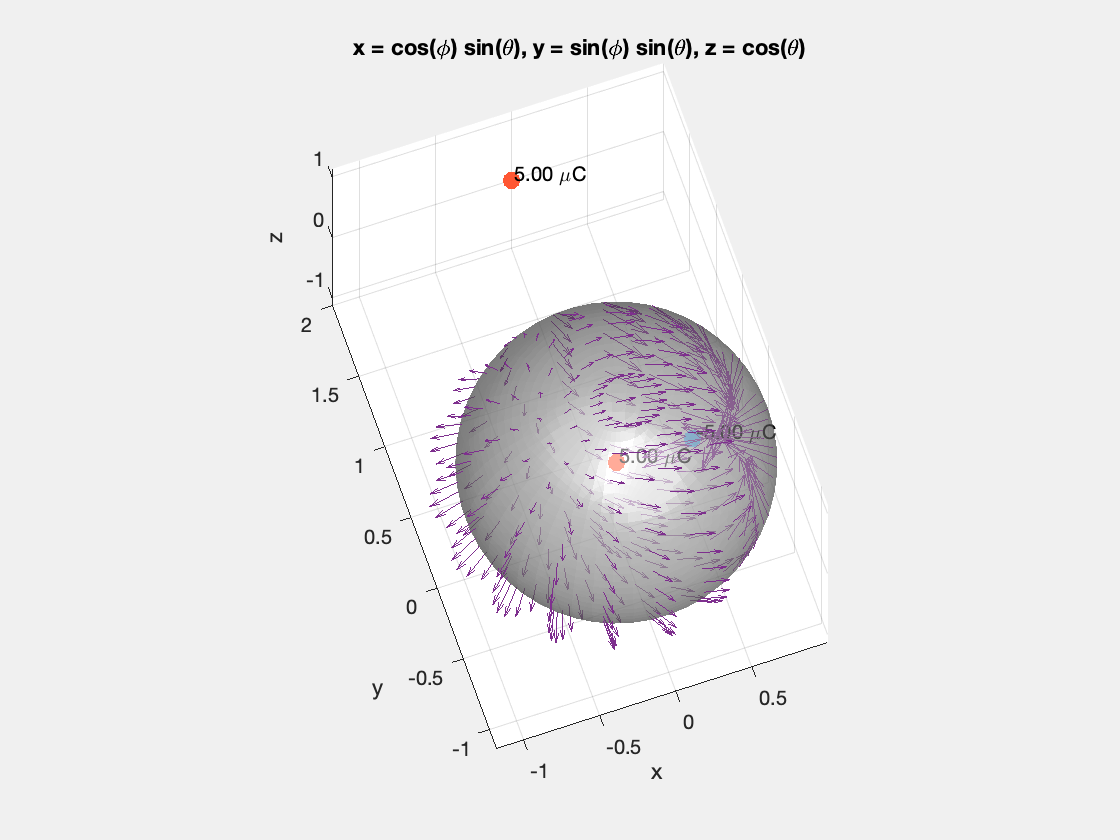

theta_array=linspace(0,pi,20);
phi_array=linspace(0,2*pi,20);
[Phi,Theta]=meshgrid(phi_array,theta_array);
xxx=subs(xx,{'phi','theta'},{Phi,Theta});
yyy=subs(yy,{'phi','theta'},{Phi,Theta});
zzz=subs(zz,{'phi','theta'},{Phi,Theta});
Ett{1}=subs(Et(1),{'phi','theta'},{Phi,Theta});
Ett{2}=subs(Et(2),{'phi','theta'},{Phi,Theta});
Ett{3}=subs(Et(3),{'phi','theta'},{Phi,Theta});
quiver3(xxx,yyy,zzz,Ett{1},Ett{2},Ett{3},5)

## Finally, let's calculate the electric flow and verify Gauss's Law.

First way to calculate the electric flow: $\Phi_E=\oint{\overrightarrow{\mathbf{E}} \cdot d\overrightarrow{\mathbf{A}}} ~~(N m^2/C)$

dA = R^2*sin(theta)*[xx yy zz]/sqrt(xx^2+yy^2+zz^2); % dtheta dphi
EdA=matlabFunction(Et*dA'); % We convert from symbolic to numeric so that it is calculated much faster
flujoE_v1=integral2(EdA,0,2*pi,0,pi) % phi goes from 0 to 2*pi and theta goes 0 to pi

flujoE_v1 = -3.6692e-11

Second way to calculate the electrical flow: $\Phi_E = \frac{q_{in}}{\epsilon_0} ~~(N m^2/C)$

eps0=625000/(22468879468420441*pi); % Vacuum permittivity constant
flujoE_v2=qin/eps0

flujoE_v2 = 0

# Let's leave here the functions that we need and that we have already used in the previous scripts

function [charge,r]=drawCharge(value,position)
if nargin<1 || isempty(value); value=sign(rand-.5)*(4*rand+1)*1e-6; end
if nargin<2 || isempty(position); position=[1.95*(rand-.5) 1.95*(rand-.5) 0]; end
charge=value; r=position;
colors={[255,87,51]/255,[93,173,226]/255};
if charge>0; c=1; else; c=2; end
plot3(r(1),r(2),r(3),'.','MarkerSize',30,'Color',colors{c});
text(r(1)+0.03,r(2)+0.03,r(3)+0.03,[num2str(charge*1e6,'%.2f'),' \muC']);
end

function E=electricField(ri,rt,qi)
c=299792458;       % Speed of light (m/s)
ke=c^2/1e7;        % Coulomb constant (Nm^2/C^2)
r = norm(rt-ri);   % Distance in the direction ri to rt
u = (rt-ri)/r;     % Unitary vector of distance in Cartesian coordinates
E = ke*qi/r^2 * u; % Electric field (E)
end